# Step 1: Read Image

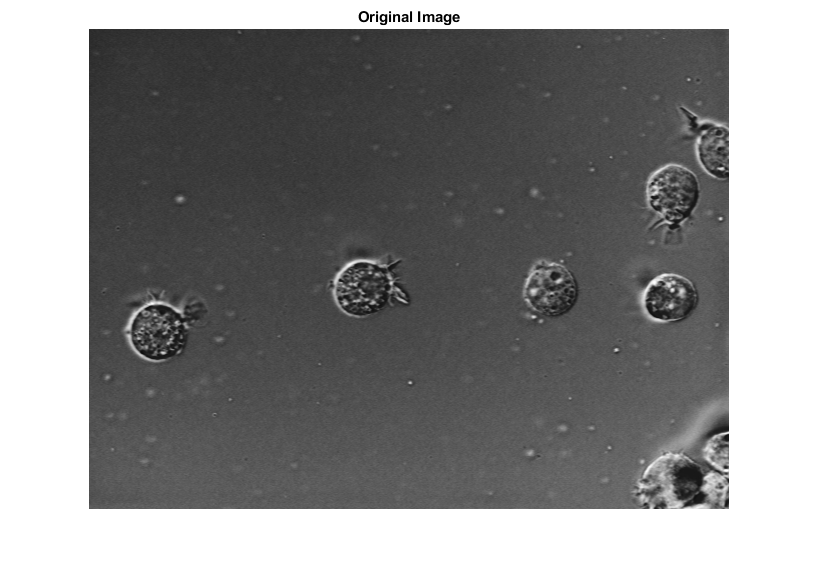

I = imread('at3_1m4_01.tif');
imshow(I)
title('Original Image');

## Step 2: Detect Entire Cell

[~,threshold] = edge(I,'sobel');
fudgeFactor = 0.5;
BWs = edge(I,'sobel',threshold * fudgeFactor);
display the resulting binary gradient mask.

Error using display
Too many input arguments.

imshow(BWs)
title('Binary Gradient Mask')

## Step 3: Dilate the Image

se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(BWs,[se90 se0]);
imshow(BWsdil)
title('Dilated Gradient Mask')

## Step 4: Fill Interior Gaps

BWdfill = imfill(BWsdil,'holes');
imshow(BWdfill)
title('Binary Image with Filled Holes')

## Step 5: Remove Connected Objects on Border

BWnobord = imclearborder(BWdfill,4);
imshow(BWnobord)
title('Cleared Border Image')

## Step 6: Smooth the Object

seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
imshow(BWfinal)
title('Segmented Image');

## Step 7: Visualize the Segmentation

imshow(labeloverlay(I,BWfinal))
title('Mask Over Original Image')
BWoutline = bwperim(BWfinal);
Segout = I; 
Segout(BWoutline) = 255; 
imshow(Segout)
title('Outlined Original Image')